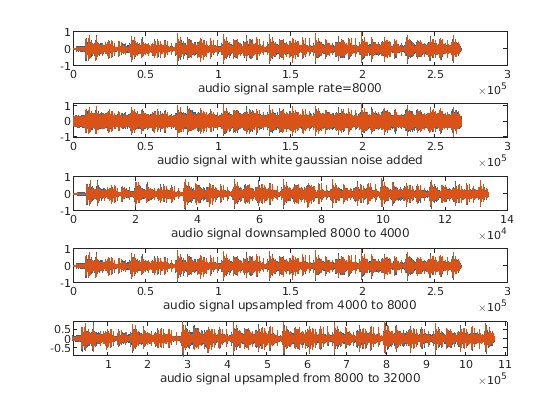

rootdirectory = 'write file path here';
[y,Fs] = audioread(fullfile(rootdirectory,'sampfile.wav'));%Given sample rate,Fs=8000
% code to resample audio
subplot (5,1,1)
plot(y)
xlabel ('audio signal sample rate=8000') 
soundsc(y,Fs)

pause(35);
%adding white gaussian noise to input audio sample
%y_wgn = awgnchan(y)
y_noise = y + 0.1*randn(size(y));
subplot(5,1,2)
plot(y_noise)
xlabel('audio signal with white gaussian noise added')
soundsc(y_noise,Fs)

%Downsampling from 8000 to 4000
Fs_new1 = 4000;
[Numer, Denom] = rat(Fs_new1/Fs);
y_new1 = resample(y, Numer, Denom);
subplot(5,1,3)
plot(y_new1)
xlabel ('audio signal downsampled 8000 to 4000') 

%Upsampaling from 4000 to 8000
Fs_new2 = 8000;
[Numer, Denom] = rat(Fs_new2/Fs);
y_new2 = resample(y, Numer, Denom);
subplot(5,1,4)
plot(y_new2)
xlabel ('audio signal upsampled from 4000 to 8000') 

%Upsampaling from 8000 to 32000
Fs_new3 = 32000;
[Numer, Denom] = rat(Fs_new3/Fs);
y_new3 = resample(y, Numer, Denom);
subplot(5,1,5)
plot(y_new3)
xlabel ('audio signal upsampled from 8000 to 32000')